Figure: Comparison of predicted fAPARmax compared to observations.Predictions are from thetheoretical model driven by environmental predictors. Observed biomes are shown with different colors; the model is incognizant of biome type. The dashed line is theregression line: the solid line is the 1:1 line. RMSE, root-mean-squared error of prediction; n, numberof observations; R, proportion of observed variance accounted for by the prediction. 

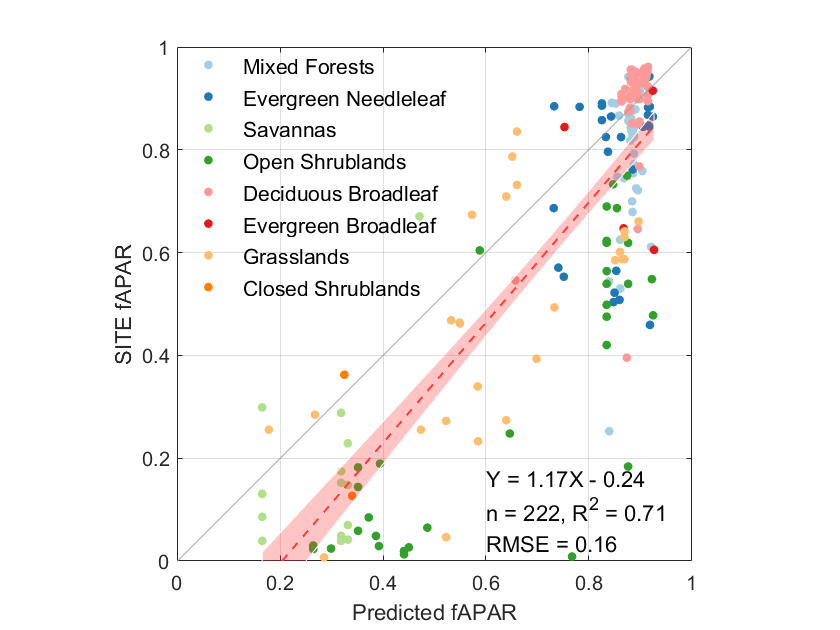

lai_output = readtable("fapar_max_data_all.csv");

f = figure;
hold on

grpIGBP = lai_output(:, "IGBP");
CT = [0.6510    0.8078    0.8902
    0.1216    0.4706    0.7059
    0.6980    0.8745    0.5412
    0.2000    0.6275    0.1725
    0.9843    0.6039    0.6000
    0.8902    0.1020    0.1098
    0.9922    0.7490    0.4353
    0.9990    0.4980         0
    0.7922    0.6980    0.8392];
h = gscatter(lai_output.fapar_max_sim, lai_output.fapar_max_obs, grpIGBP.IGBP, CT);

scatter_plot(lai_output.fapar_max_sim, lai_output.fapar_max_obs, ...
    'PlotDisp', 'off', 'StatisLocation','southeast','AxisLim',[0 1 0 1], ...
    'PlotConf','on','reglinestyle','-','RegLineColor', [255,59,59]/255,'StatisDispItem', 'r2+rmse+equ+num');

xlabel('Predicted fAPAR')  
ylabel('SITE fAPAR')

xticks(0:0.2:1)
yticks(0:0.2:1)

axis equal
axis([0 1 0 1])
legend(h,'Box','off','FontSize',10.5)
hold off;

grid on
legend('Position',[0.18768,0.51504,0.36845,0.41151])
exportgraphics(gcf, fullfile('./', 'Figure 1.png'),"Resolution",600);